TILTING CONTROL

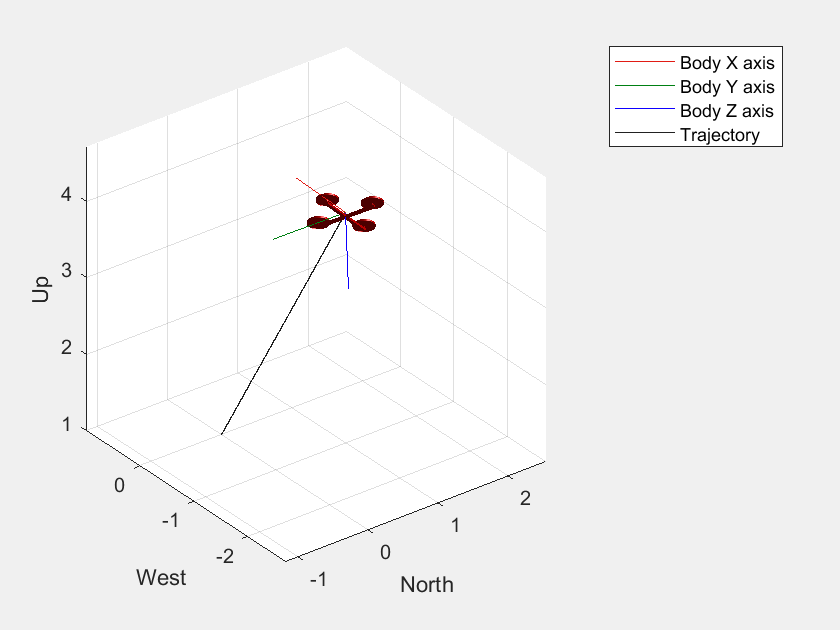

sim('tilting_control_voliro_template.slx');

pos = ans.pos.data;
pos_des = ans.pos_des.data;
len = length(ans.pos_des.data);
t = 0 : (len-1);
lin_acc_des = ans.lin_acc_des.data;
lin_acc = ans.lin_acc.data;
lin_vel_des = ans.lin_vel_des.data;
lin_vel = ans.lin_vel.data;
err_p = ans.err_p.data;
dot_err_p = ans.dot_err_p.data;
err_R = ans.err_R.data;
err_W = ans.err_W.data;
Rb = ans.Rb.data;
uw = ans.uw.data;
alpha = ans.alfa.data;
f_b = ans.f_b.data;
tau_b = ans.tau_b.data;
omega_bb = ans.omega_bb.data;
omega_bb_des = ans.omega_bb_des.data;
euler_angles = ans.euler_angles.data;
euler_angles_des = ans.euler_angles_des.data;
yaw = squeeze(euler_angles(1,1,:));
yaw_des = squeeze(euler_angles_des(1,1,:));
pitch = squeeze(euler_angles(2,1,:));
pitch_des = squeeze(euler_angles_des(2,1,:));
roll = squeeze(euler_angles(3,1,:));
roll_des = squeeze(euler_angles_des(3,1,:));

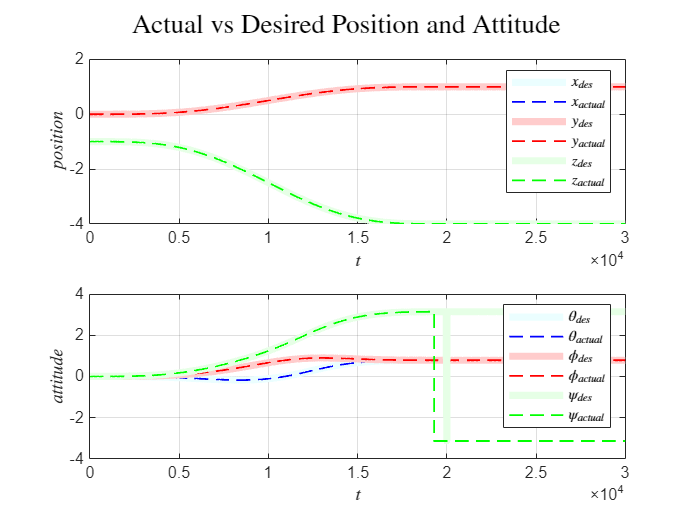

figure
subplot(2,1,1)
plot(t, pos_des(:,1), 'LineWidth', 4,'Color', [235/255, 254/255, 255/255], 'DisplayName', '$x_{des}$');
hold on
plot(t, pos(:,1), 'LineWidth', 1, 'Color', 'b', 'LineStyle', '--', 'DisplayName', '$x_{actual}$');
plot(t, pos_des(:,2), 'LineWidth', 4,'Color', [1, 0.8, 0.8] , 'DisplayName', '$y_{des}$');
plot(t, pos(:,2), 'LineWidth', 1, 'Color', 'r', 'LineStyle', '--', 'DisplayName', '$y_{actual}$');
plot(t, pos_des(:,3), 'LineWidth', 4,'Color', 	[0.9, 1, 0.9], 'DisplayName', '$z_{des}$');
plot(t, pos(:,3), 'LineWidth', 1, 'Color', 'g', 'LineStyle', '--', 'DisplayName', '$z_{actual}$');
xlabel('$t$','Interpreter','latex')
ylabel('$position$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(2,1,2)
plot(t, roll_des, 'LineWidth', 4,'Color', [235/255, 254/255, 255/255], 'DisplayName', '$\theta_{des}$');
hold on
plot(t, roll, 'LineWidth', 1, 'Color', 'b', 'LineStyle', '--', 'DisplayName', '$\theta_{actual}$');
plot(t, pitch_des, 'LineWidth', 4,'Color', [1, 0.8, 0.8] , 'DisplayName', '$\phi_{des}$');
plot(t, pitch, 'LineWidth', 1, 'Color', 'r', 'LineStyle', '--', 'DisplayName', '$\phi_{actual}$');
plot(t, yaw_des, 'LineWidth', 4,'Color', 	[0.9, 1, 0.9] , 'DisplayName', '$\psi_{des}$');
plot(t, yaw, 'LineWidth', 1, 'Color', 'g', 'LineStyle', '--', 'DisplayName', '$\psi_{actual}$');
xlabel('$t$','Interpreter','latex')
ylabel('$attitude$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('Actual vs Desired Position and Attitude','Interpreter','latex')
print(gcf, 'ex5_pos_vs_despos_and_yaw', '-dpdf', '-r150'); 

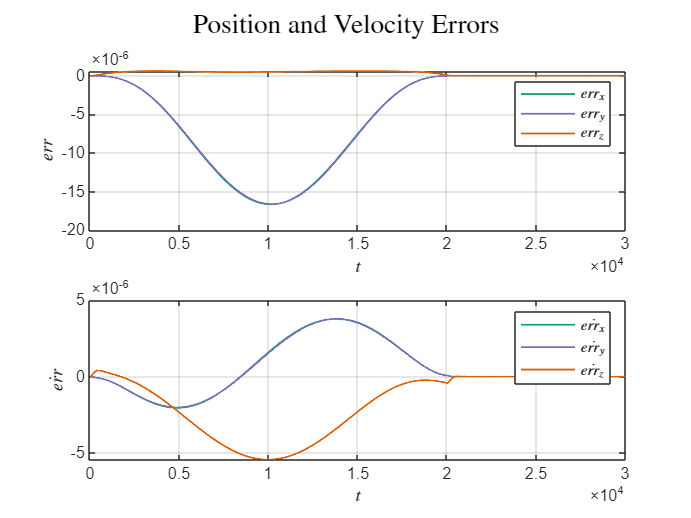

figure
subplot(2,1,1)
plot(t, err_p(:,1), 'LineWidth', 1, 'Color', '#1b9e77', 'DisplayName', '$err_x$'); hold on;
plot(t, err_p(:,2), 'LineWidth', 1, 'Color', '#7570b3', 'DisplayName', '$err_y$');
plot(t, err_p(:,3), 'LineWidth', 1, 'Color', '#d95f02','DisplayName', '$err_z$');
xlabel('$t$','Interpreter','latex')
ylabel('$err$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(2,1,2)
plot(t, dot_err_p(:,1), 'LineWidth', 1,  'Color', '#1b9e77','DisplayName', '$\dot{err_x}$'); hold on;
plot(t, dot_err_p(:,2), 'LineWidth', 1, 'Color', '#7570b3', 'DisplayName', '$\dot{err_y}$');
plot(t, dot_err_p(:,3), 'LineWidth', 1, 'Color', '#d95f02', 'DisplayName', '$\dot{err_z}$');
xlabel('$t$','Interpreter','latex')
ylabel('$\dot{err}$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('Position and Velocity Errors','Interpreter','latex')
print(gcf, 'ex5_pos_&_vel_err', '-dpdf', '-r150'); 

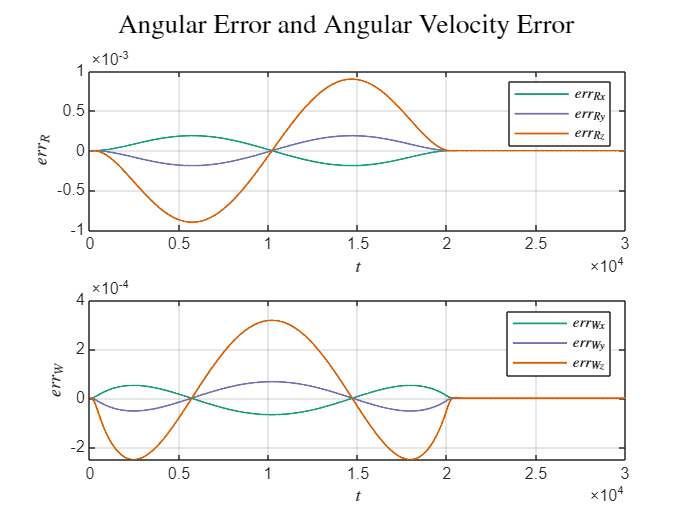

figure
subplot(2,1,1)
plot(t, err_R(:,1), 'LineWidth', 1, 'Color', '#1b9e77', 'DisplayName', '$err_{Rx}$'); hold on;
plot(t, err_R(:,2), 'LineWidth', 1, 'Color', '#7570b3', 'DisplayName', '$err_{Ry}$');
plot(t, err_R(:,3), 'LineWidth', 1, 'Color', '#d95f02','DisplayName', '$err_{Rz}$');
xlabel('$t$','Interpreter','latex')
ylabel('$err_R$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(2,1,2)
plot(t, err_W(:,1), 'LineWidth', 1,  'Color', '#1b9e77','DisplayName', '$err_{Wx}$'); hold on;
plot(t, err_W(:,2), 'LineWidth', 1, 'Color', '#7570b3', 'DisplayName', '$err_{Wy}$');
plot(t, err_W(:,3), 'LineWidth', 1, 'Color', '#d95f02', 'DisplayName', '$err_{Wz}$');
xlabel('$t$','Interpreter','latex')
ylabel('$err_W$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('Angular Error and Angular Velocity Error','Interpreter','latex')
print(gcf, 'ex5_ang_&_ang_vel_err', '-dpdf', '-r300');

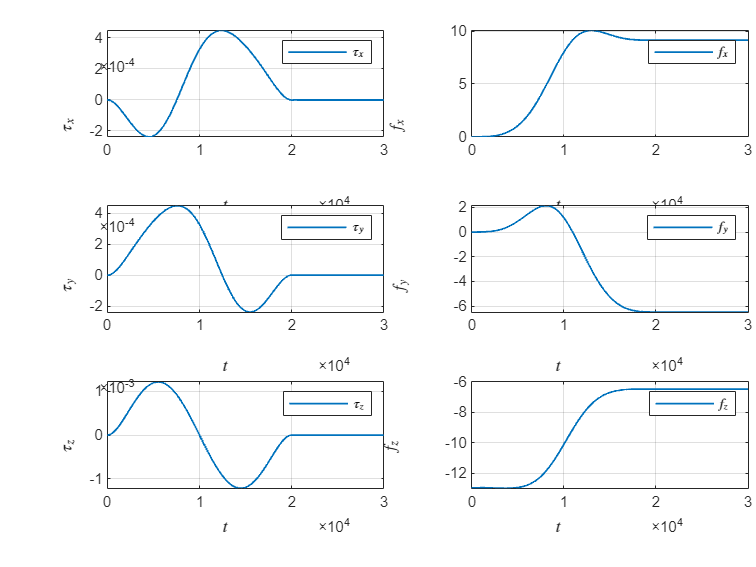

figure
subplot(3,2,1)
plot(t, tau_b(:,1), 'LineWidth', 1, 'DisplayName', '$\tau_x$');
xlabel('$t$','Interpreter','latex')
ylabel('$\tau_x$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,3)
plot(t, tau_b(:,2), 'LineWidth', 1, 'DisplayName', '$\tau_y$');
xlabel('$t$','Interpreter','latex')
ylabel('$\tau_y$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,5)
plot(t, tau_b(:,3), 'LineWidth', 1, 'DisplayName', '$\tau_z$');
xlabel('$t$','Interpreter','latex')
ylabel('$\tau_z$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('forces and torques','Interpreter','latex')
subplot(3,2,2)
plot(t, f_b(:,1), 'LineWidth', 1, 'DisplayName', '$f_x$');
xlabel('$t$','Interpreter','latex')
ylabel('$f_x$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,4)
plot(t, f_b(:,2), 'LineWidth', 1, 'DisplayName', '$f_y$');
xlabel('$t$','Interpreter','latex')
ylabel('$f_y$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,6)
plot(t, f_b(:,3), 'LineWidth', 1, 'DisplayName', '$f_z$');
xlabel('$t$','Interpreter','latex')
ylabel('$f_z$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');

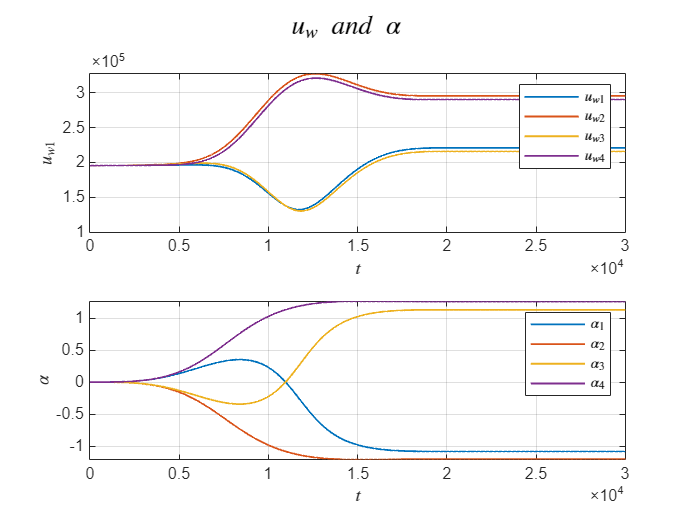

figure
subplot(2,1,1)
plot(t, uw(:,1), 'LineWidth', 1, 'DisplayName', '$u_{w1}$'); hold on;
plot(t, uw(:,2), 'LineWidth', 1, 'DisplayName', '$u_{w2}$');
plot(t, uw(:,3), 'LineWidth', 1, 'DisplayName', '$u_{w3}$');
plot(t, uw(:,4), 'LineWidth', 1, 'DisplayName', '$u_{w4}$');
xlabel('$t$','Interpreter','latex')
ylabel('$u_{w1}$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(2,1,2)
plot(t, alpha(:,1), 'LineWidth', 1, 'DisplayName', '$\alpha_1$'); hold on;
plot(t, alpha(:,2), 'LineWidth', 1, 'DisplayName', '$\alpha_2$');
plot(t, alpha(:,3), 'LineWidth', 1, 'DisplayName', '$\alpha_3$');
plot(t, alpha(:,4), 'LineWidth', 1, 'DisplayName', '$\alpha_4$');
xlabel('$t$','Interpreter','latex')
ylabel('$\alpha$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('$u_w \ and \ \alpha$','Interpreter','latex')
print(gcf, 'ex5_uT', '-dpdf', '-r150'); 